## HW 5, Question 1

#### Hannah Verdonk

**Part A**

We are going to simulate diffusion in a FRAP experiment using a "spread the butter" approach.

Given that, at time t= 0, a window of a width of 1μm centered around the middle of the cell is bleached, it makes sense to track the diffusion of these particles out of that window, rather than trying to calculate the diffusion of fluorescent particles diffusing into that window on two sides. 

First, let's define the model parameters.

N0=100;             %number of molecules
D=10;               %diffusion constant in um^2/s
L=2;                %length of the cell in um
TotalTime=1E-1;     %in s (this means 1(10)^-1 s, or 100 ms)

The simulation parameters are

dx=0.1;             %in um (originally 0.01)
M=L/dx;             %number of imaginary boxes in the E. coli cell
k=D/(dx^2);         %jump rate of a single molecule
dt=(1/k)/10;        %time step in s
Timepoints=TotalTime/dt; %Number of timepoints in the simulation

Now we need to define the matrix we'll use to keep track of the molecules as well as the initial condition. The matrix N we'll use has TotalTime/dt rows (number of time points) and M columns (number of imaginary boxes).

First, we create a matrix of this size that is full of zeros. 

N=zeros(1000,M);

I have the N matrix. Before I run the simulation I need to "seed it" using the initial condiiton.

N(1, 1:(M/4))=N0;   %the bleached area reaches from one quarter of the cell's 
N(1, (3*M/4):M)=N0; %length to three quarters of the cell's length

We're ready to run the simulation. I'm going to need two for-loops, one that goes over time and one that goes over the box number. For the latter for-loop, I need to be careful about box 1 and box M.

%for loop for time
for j=2:TotalTime/dt
    %for-loop for boxes 2 through M-1
    for i=2:M-1
       N(j, i)=N(j-1,i)+N(j-1,i+1)*k*dt...
           +N(j-1, i-1)*k*dt-2*N(j-1,i)*k*dt;
    end
    N(j, 1) = N(j-1,1)+N(j-1,2)*k*dt-N(j-1,1)*k*dt; %box 1
    N(j, M)=N(j-1,M)+N(j-1,M-1)*k*dt-N(j-1,M)*k*dt; %box M
end

%row position j (time)
%column position i (box #)
%initial plus molec from right box

Finally, let's plot the distribution at different time points. To do this, I create a vector that keeps track of the box number.

Box=1:M;

Now we will plot the first and last time points, as well as three time points in the middle of the diffusion experiment. 

(100ms/1000 timepoints = 0.1 ms per timepoint)

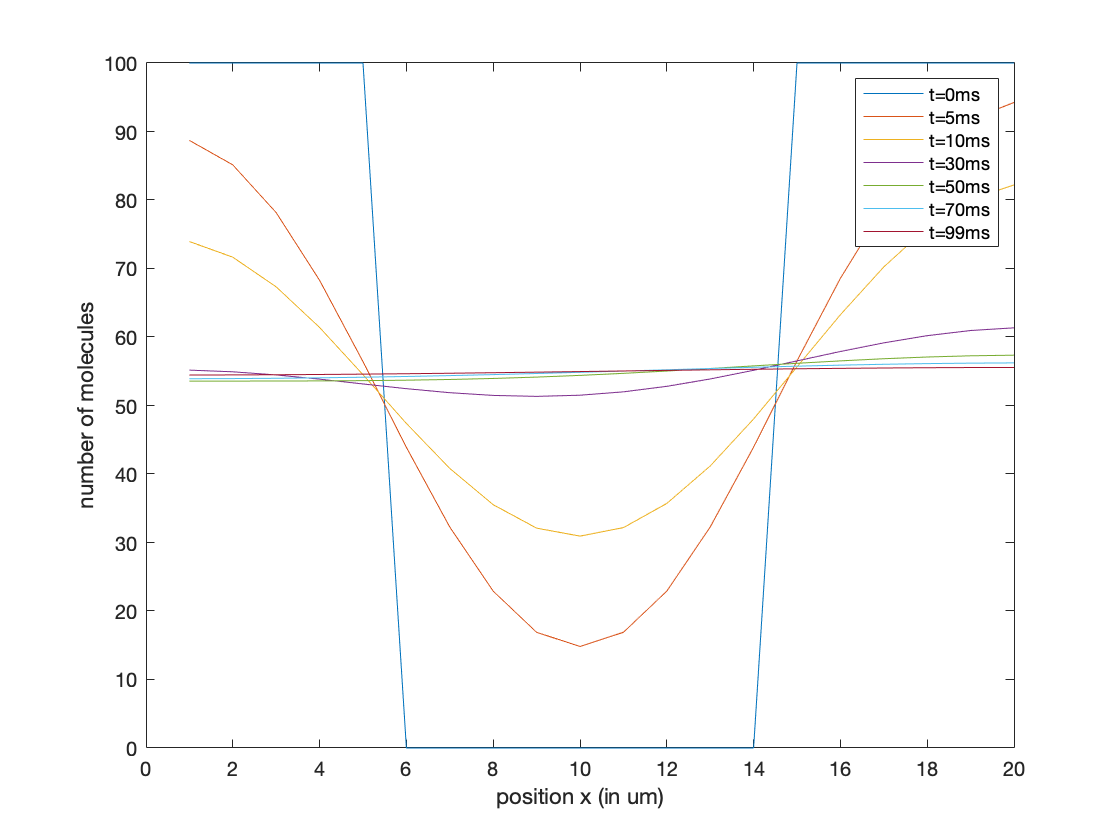

plot(Box, N(1,:))
hold on
plot(Box, N(50,:))
plot(Box, N(100,:))
plot(Box, N(300,:))
plot(Box, N(500,:))
plot(Box, N(700,:))
plot(Box, N(999,:))
hold off
xlabel('position x (in um)')
ylabel('number of molecules')
legend('t=0ms', 't=5ms', 't=10ms', 't=30ms', 't=50ms', 't=70ms', 't=99ms')

**Part B**

Now I will estimate the recovery time as the time it takes for the fluorescence in the center of the bleached region to reach 2/3 of its maximum value. To do so, I will estimate the recovery times for different values of D, then plot these times against those values of D.

For D=2 um^2/s, the recovery time is roughly 700ms.

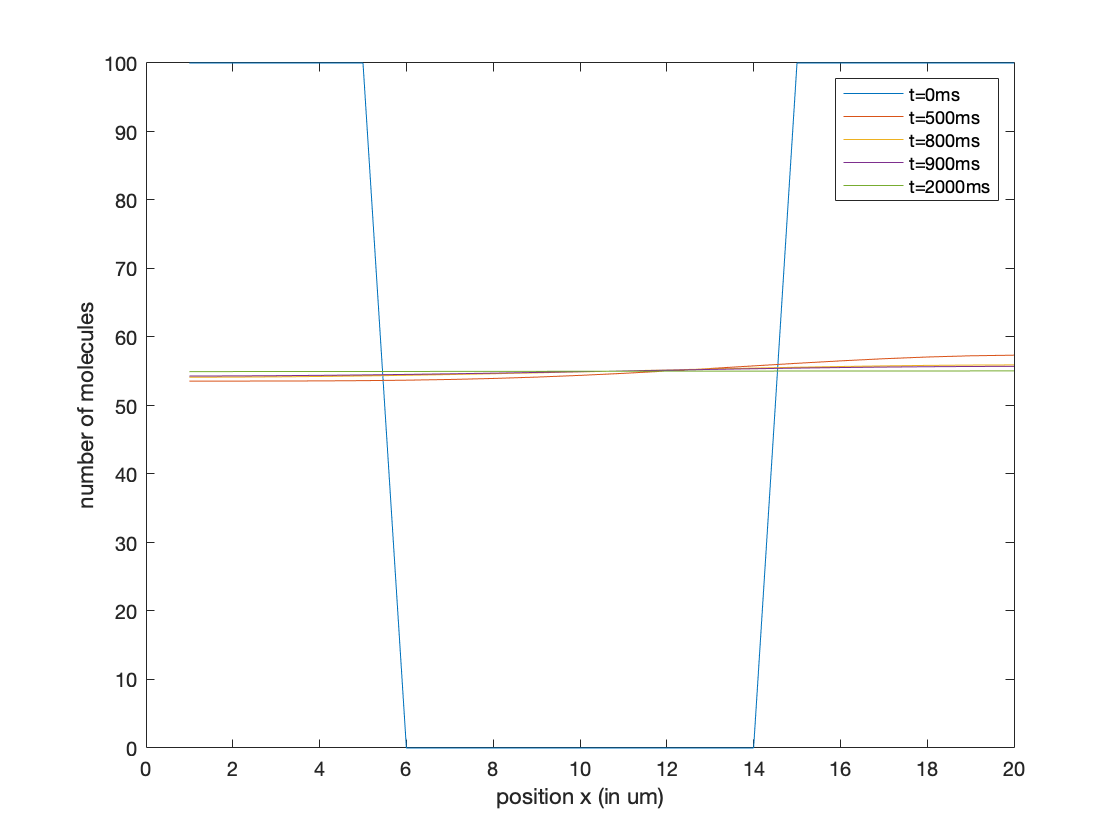

D=2;                %diffusion constant in um^2/s
L=2;                %length of the cell in um
N0=100;             %number of molecules
dx=0.1;             %in um (originally 0.01)
M=L/dx;             %number of imaginary boxes in the E. coli cell
k=D/(dx^2);         %jump rate of a single molecule
dt=(1/k)/10;        %time step in s
TotalTime=1;        %in s (1000 ms)

Box=1:M;            %vector to track position
N=zeros(1000,M);    %reinitialize the N matrix
N(1, 1:(M/4))=N0;   %re-seed N matrix 
N(1, (3*M/4):M)=N0;

%for loop for time
for j=2:TotalTime/dt
    %for-loop for boxes 2 through M-1
    for i=2:M-1
       N(j, i)=N(j-1,i)+N(j-1,i+1)*k*dt...
           +N(j-1, i-1)*k*dt-2*N(j-1,i)*k*dt;
    end
    N(j, 1) = N(j-1,1)+N(j-1,2)*k*dt-N(j-1,1)*k*dt; %box 1
    N(j, M)=N(j-1,M)+N(j-1,M-1)*k*dt-N(j-1,M)*k*dt; %box M
end

plot(Box, N(1,:))
hold on
plot(Box, N(500,:))
plot(Box, N(800,:))
plot(Box, N(900,:))
plot(Box, N(1999,:))
hold off
xlabel('position x (in um)')
ylabel('number of molecules')
legend('t=0ms', 't=500ms', 't=800ms', 't=900ms' , 't=2000ms')

For D=10 um^2/s, the recovery time as found in Part A is about 70 ms.

For D=20 um^2/s, the recovery time is roughly 30ms.

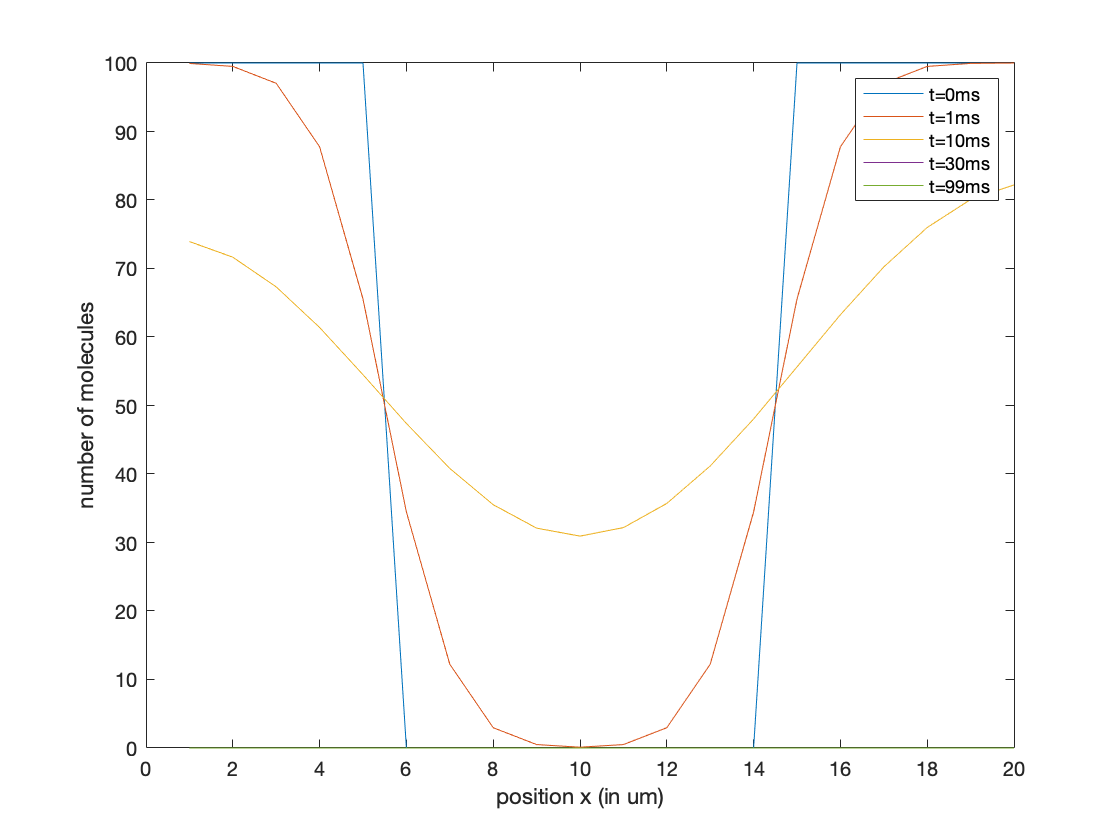

D=20;               %diffusion constant in um^2/s
L=2;                %length of the cell in um
N0=100;             %number of molecules
dx=0.1;             %in um (originally 0.01)
M=L/dx;             %number of imaginary boxes in the E. coli cell
k=D/(dx^2);         %jump rate of a single molecule
dt=(1/k)/10;        %time step in s
TotalTime=1E-2;     %in s (this means 1(10)^-2 s, or 10 ms)

Box=1:M;            %vector to track position
N=zeros(1000,M);    %reinitialize the N matrix
N(1, 1:(M/4))=N0;   %re-seed N matrix 
N(1, (3*M/4):M)=N0;

%for loop for time
for j=2:TotalTime/dt
    %for-loop for boxes 2 through M-1
    for i=2:M-1
       N(j, i)=N(j-1,i)+N(j-1,i+1)*k*dt...
           +N(j-1, i-1)*k*dt-2*N(j-1,i)*k*dt;
    end
    N(j, 1) = N(j-1,1)+N(j-1,2)*k*dt-N(j-1,1)*k*dt; %box 1
    N(j, M)=N(j-1,M)+N(j-1,M-1)*k*dt-N(j-1,M)*k*dt; %box M
end

plot(Box, N(1,:))
hold on
plot(Box, N(10,:))
plot(Box, N(100,:))
plot(Box, N(200,:))
plot(Box, N(999,:))
hold off
xlabel('position x (in um)')
ylabel('number of molecules')
legend('t=0ms', 't=1ms', 't=10ms', 't=30ms' , 't=99ms')

Now I can plot value of D vs FRAP recovery time.

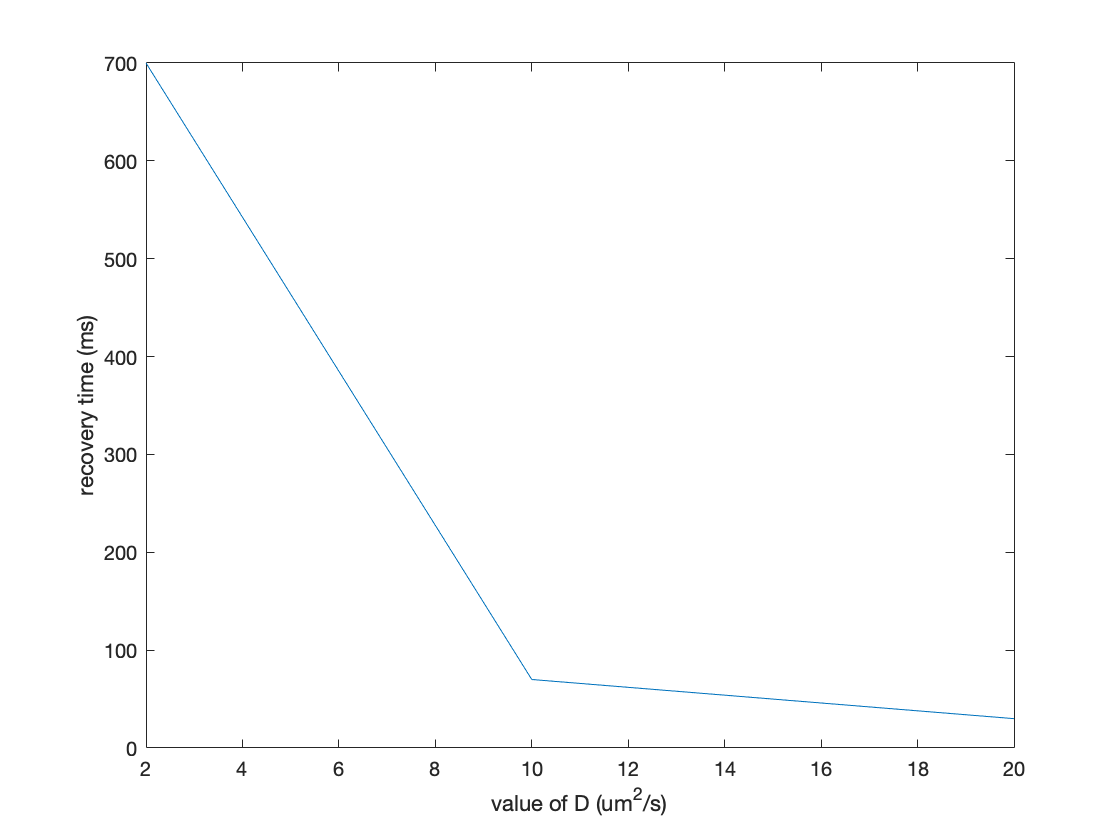

Dvalues=[2,10,20];
RecTimes=[700, 70, 30];

plot(Dvalues, RecTimes)
xlabel('value of D (um^2/s)')
ylabel('recovery time (ms)')

2/3 of 70ms is roughly 47ms. Therefore, it takes about 47ms for the bleached region to reach 2/3 of it's maximum value.